## Definitions

### Define State-space

**xp** = [x; x_dot; z; z_dot]

**up** = [x_ddot; z_ddot]

**yp** = [x; z]

#### Equations

**xp(k+1)** = A**xp(k)** + B**up(k)**

**yp(k) **= C**xp(k)**

clear

dt = 0.1;

A_p = [1 dt 0 0;
       0 1  0 0;
       0 0  1 dt;
       0 0  0 1;];

B_p = [dt^2/2 0;
       dt     0;
       0      dt^2/2;
       0      dt;];

C_p = [1 0 0 0;
       0 0 1 0;];

### Define Square Obstacle Parameters

O = {y|E_l*y < f_l}

E_l = [1 0;
      -1 0;
       0 1;
       0 -1;];

f_l = [60;
      -40;
       60;
      -40;];

## Simulation

alpha_x = 0.1;
alpha_u = 0.00001;
num_states = 4;
num_controls = 2;
num_modes = 2; % const for now

N = 3;
x_goal = [10; 0; 5; 0];

% Define the number of decision variables
num_t_N = 1;
num_t_x = N-1;
num_t_u = N-1;
num_x_p = N * num_states;
num_u_p = (N-1) * num_controls;
total_vars = num_t_N + num_t_x + num_t_u + num_x_p + num_u_p + num_modes;

num_contraints = 2*(num_x_p+num_u_p)+num_modes*num_u_p;

The cost function (objective)


$$J_{\mathrm{p}}\left(\left\{x_p\right\},\left\{u_p\right\}\right)=\left\|x_{\text {goal }}-x_p\left(k_p+N\right)\right\|_{\infty}+\sum_{j=k_p}^{k_p+N-1} \alpha_x\left\|x_{\text {goal }}-x_p(j)\right\|_{\infty}+\alpha_u\left\|u_p(j)\right\|_{\infty}$$


can be rewriten as a linear program


$$J_{\mathrm{p}}=t_N+\sum_{j=k_p}^{k_p+N-1} \alpha_x t_x(j)+\alpha_u t_u(j)$$
 

with constraints

$
t_N \geq\left|x_{\text {goal }, i}-x_p\left(k_p+N\right)_i\right| \quad \forall i \\
t_x(j) \geq \alpha_x\left|x_{\text {goal }, i}-x_p(j)_i\right| \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right] \\
t_u(j) \geq \alpha_u\left|u_p(j)_i\right| \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right]
\end{gathered}$.

The MATLAB function intlinprog finds the minimum of a problem specified by

$\min _x f^T x \text { subject to }\left\{\begin{array}{l}
x \text { (intcon) are integers } \\
A \cdot x \leq b \\
A e q \cdot x=b e q \\
l b \leq x \leq u b .
\end{array}\right.$.

$x$ is definded implicitly as


$$x=\left\lbrack \begin{array}{c}
{\mathit{\mathbf{x}}}_p \left(k_p \right):{\mathit{\mathbf{x}}}_p \left(k_p +N\right)\\
{\mathit{\mathbf{u}}}_p \left(k_p \right):{\mathit{\mathbf{u}}}_p \left(k_p +N-1\right)\\
t_x \left(k_p \right):t_x \left(k_p +N-1\right)\\
t_N \\
t_u \left(k_p \right):t_u \left(k_p +N-1\right)\\
d_i 
\end{array}\right\rbrack$$
 

and $f$ is defined as

$f=$$\left\lbrack \begin{array}{c}
\left.0\cdot {\left(\mathit{\mathbf{x}}\right.}_p \left(k_p \right):{\mathit{\mathbf{x}}}_p \left(k_p +N\right)\right)\\
0\cdot \left({\mathit{\mathbf{u}}}_p \left(k_p \right):{\mathit{\mathbf{u}}}_p \left(k_p +N-1\right)\right)\\
\alpha_x \cdot \left(t_x \left(k_p \right):t_x \left(k_p +N-1\right)\right)\\
t_N \\
\alpha_u \cdot \left(t_u \left(k_p \right):t_u \left(k_p +N-1\right)\right)\\
0\cdot d_i 
\end{array}\right\rbrack$.

Optimization variable $d_i$ is a binary variable to choose the low level control mode.

f = [zeros(num_x_p,1);
     zeros(num_u_p,1);
     alpha_x*ones(num_t_x,1);
     ones(num_t_N);
     alpha_u*ones(num_t_u,1);
     zeros(num_modes,1)];

The constraints 


$$\left|x_{\text {goal }, i}-x_p\left(k_p+N\right)_i\right| \leq t_N\quad \forall i \\
\left|x_{\text {goal }, i}-x_p(j)_i\right| \leq t_x(j) \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right] \\
\left|u_p(j)_i\right| \leq t_u(j) \quad \forall i, \forall j \in\left[k_p, k_p+N-1\right]
\end{gathered}$$


are implement using matrix $A$ and vector $b$ in the equation

 $A \cdot x \leq b$.

The equations are rearrange to become compliant with the equation above:


$$\left\lbrack \begin{array}{c}
-x_p {\left(j\right)}_i -t_x \left(j\right)\le -x_{\textrm{goal},i} \;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack \\
-x_p {\left(k_p +N\right)}_i -t_N \le -x_{\textrm{goal},i} \;\;\;\;\;\;\forall i\\
u_p {\left(j\right)}_i -t_u \left(j\right)\le 0\;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack \\
x_p {\left(j\right)}_i -t_x \left(j\right)\le x_{\textrm{goal},i} \;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack \\
x_p {\left(k_p +N\right)}_i -t_N \le x_{\textrm{goal},i} \;\;\;\;\;\;\forall i\\
{-u}_p {\left(j\right)}_i -t_u \left(j\right)\le 0\;\;\;\;\;\forall i,\forall j\in \left\lbrack k_p ,k_p +N-1\right\rbrack 
\end{array}\right\rbrack$$


%% Manipulating matrix A and b

A = zeros(num_contraints,total_vars);
index = 1; % helper indexer

% row 1 & 2
A(1:num_x_p,1:num_x_p) = -eye(num_x_p,num_x_p);
for i = 1:N 
    A(index:index+num_states-1, num_x_p+num_u_p+i) = -ones(num_states,1);
    index = index + num_states;
end

% row 3
A(index:index+num_u_p-1,index:index+num_u_p-1) = eye(num_u_p,num_u_p);
for i = 1:N-1
    A(index:index+num_controls-1,num_x_p+num_u_p+N+i) = -ones(num_controls,1);
    index = index + num_controls;
end

% row 4 & 5
A(index:index+num_x_p-1,1:num_x_p) = eye(num_x_p,num_x_p);
for i = 1:N
    A(index:index+num_states-1, num_x_p+num_u_p+i) = -ones(num_states,1);
    index = index + num_states;
end

% row 6
A(index:index+num_u_p-1,num_x_p+1:num_x_p+num_u_p) = -eye(num_u_p,num_u_p);
for i = 1:N-1
    A(index:index+num_controls-1,num_x_p+num_u_p+N+i) = -ones(num_controls,1);
    index = index + num_controls;
end

M_big = 10000;

A(index:index+num_u_p-1,num_x_p+1:num_x_p+num_u_p) = eye(num_u_p,num_u_p);
A(index:index+num_u_p-1,num_x_p+num_u_p+num_t_x+num_t_N+num_t_u+1) = M_big*ones(num_u_p,1);
index = index + num_u_p;
A(index:index+num_u_p-1,num_x_p+1:num_x_p+num_u_p) = eye(num_u_p,num_u_p);
A(index:index+num_u_p-1,num_x_p+num_u_p+num_t_x+num_t_N+num_t_u+2) = M_big*ones(num_u_p,1);

b = zeros(num_contraints,1);
index = 1;
for i = 1:N
    b(index:index+num_states-1) = -x_goal;
    b(index+num_x_p+num_u_p:index+num_x_p+num_u_p+num_states-1) = x_goal;
    index = index + num_states;
end
index = index+num_x_p+num_u_p+num_states;
G1 = 100;
G2 = 200;
b(index:index+num_u_p-1) = G1 + M_big;
index = index + num_u_p;
b(index:index+num_u_p-1) = G2 + M_big;


To implement the double integrator dynamics, we use the equality constraint

$Aeq \cdot x = beq$.

We manipulate $\textrm{Aeq}$ and $\textrm{beq}$ to have equations


$$\left\lbrack \begin{array}{c}
x_p \left(k_p +j+1\right)-A_p x_p \left(k_p +j\right)-B_p u_p \left(k_p +j\right)\;\;\;\;\;\;\;\forall j\in \left\lbrack 0,\ldotp \ldotp \ldotp ,N-1\right\rbrack \\
x_p =\textrm{intial}\;\textrm{condition}\\
\sum_i d_i =1
\end{array}\right\rbrack$$


%% Manipulating Aeq and beq

Aeq = zeros(N*num_states+1, total_vars);

% Inserting x_p(k_p+j+1)
Aeq(1:(N-1)*num_states,num_states+1:N*num_states) = eye((N-1)*num_states,(N-1)*num_states);

% Inserting A_p in every equation
index = 1;
for i = 1:N-1
    Aeq(index:index+num_states-1,index:index+num_states-1) = -A_p;
    index = index + num_states;
end

% Initial condition
Aeq(index:index+num_states-1,1:num_states) = eye(num_states,num_states);
index = index + num_states;

%
Aeq(index,end-1:end) = ones(1,num_modes);

% Inserting B_p in every equation
index_row = 1;
index_col = num_states*N+1;
for i = 1:N-1
    Aeq(index_row:index_row+num_states-1,index_col:index_col+num_controls-1) = -B_p;
    index_row = index_row + 4;
    index_col = index_col + 2;   
end

beq = zeros(N*num_states+1,1);
beq(end) = 1;

% Solve the linear program
sim_time = 50;
out = zeros(sim_time, num_states);

for i = 1:sim_time
    x = intlinprog(f, [total_vars-1 total_vars], A, b, Aeq, beq);
    out(i,:) = x(5:8)';
    beq((N-1)*num_states+1:N*num_states) = x(5:8);
end

Running HiGHS 1.6.0: Copyright (c) 2023 HiGHS under MIT licence terms
Presolving model
40 rows, 17 cols, 86 nonzeros
36 rows, 13 cols, 76 nonzeros

Solving MIP model with:
   36 rows
   13 cols (0 binary, 1 integer, 0 implied int., 12 continuous)
   76 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   -inf            inf                  inf        0      0      0         0     0.0s
 R       0       0         0   0.00%   10.57020408     10.57020408        0.00%        0      0      0        24     0.1s

Solving report
  Status            Optimal
  Primal bound      10.5702040816
  Dual bound        10.5702040816
  Gap               0% (tolerance: 0.01%)
  Solution status   feasible
                    10.5702040816 (objective)
                   

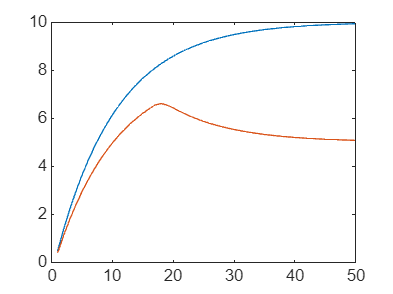

figure;
plot(1:length(out), out(:,1));
hold on;
plot(1:length(out), out(:,3));